clc, clear all;
addpath(genpath('C:\Users\caoshuning\Desktop\Bayer2RGB\bayer图像\'));
suffix = '.bmp'

suffix = '.bmp'

dataname = '20190802_wei2_Raw';
datapath = sprintf('%s','bayer图像/',dataname,'_',suffix(2:end))

datapath = 'bayer图像/20190802_wei2_Raw_bmp'


if ~exist('bayer图像/color_split','dir')
    mkdir bayer图像/color_split
end

SaveFold = 'bayer图像/color_split/'

SaveFold = 'bayer图像/color_split/'

if ~exist(sprintf('%s',SaveFold,dataname), 'dir')
    mkdir(sprintf('%s',SaveFold,dataname))
end


DATA = dir(fullfile(datapath, '*.bmp'))

DATA = 包含以下字段的 4070×1 struct 数组:
    name
    folder
    date
    bytes
    isdir
    datenum


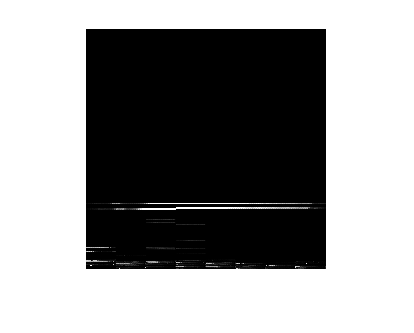

for i = 1:length(DATA)
    
    BAYER = imread([datapath,'/',DATA(i).name]);
    imshow(BAYER);
    [R, G0, G1, B] = BayerColorSplit(BAYER);
    
    %以下坐标都是从1开始计算
    g1 = G1(1:2:end,1:2:end);%(temp_x==1&&temp_x==1)%G1坐标都是奇数
    g0 = G0(2:2:end,2:2:end);%(temp_x==0&&temp_y==0)%G0坐标都是偶数
    r = R(1:2:end,2:2:end);%(temp_x==0 && temp_y==1)%R偶数行，奇数列
    b = R(2:2:end,1:2:end);%(temp_x==1 && temp_y==0 )%B奇数行，偶数列
    
    imwrite(g0,[sprintf('%s',SaveFold,dataname),'/',num2str(i),'_','g0','.bmp'])
    imwrite(g1,[sprintf('%s',SaveFold,dataname),'/',num2str(i),'_','g1','.bmp'])
    imwrite(r,[sprintf('%s',SaveFold,dataname),'/',num2str(i),'_','r','.bmp'])
    imwrite(b,[sprintf('%s',SaveFold,dataname),'/',num2str(i),'_','b','.bmp'])
end